nBounces = 2;
timeout = 20; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

%testing git


p_0 = [20, 25, 100];
v_0 = [-1, 0, 5];

clf; hold on;
plot3(0, 0, 0, 'ro');
plot3(p_0(1), p_0(2), p_0(3), 'gx');

origin = [0; 0; 0];
% normal2D = table_angle_fzero(p_0([1, 3]), v_0([1, 3]));
% normal = [normal2D(1); 0; normal2D(2)]
normal = table_angle_fzero_3d(p_0, v_0)

h = -0.0072

d =    14.9434
   25.0000


v_impact2 =    -1.0000
         0
  -44.5549


vec_toss =    -5.0566
         0
 -100.0072


normal =    -0.0008
   -0.0151
    0.9999



if normal(3) < 0
    normal = -normal;
end

[T, States, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], coeff_restitution, origin, normal, g);
plot3(States(:, 1), States(:, 2), States(:, 3));
view(3);

States(T == endTimes(1), :) % the location of the first bounce

ans =    14.9522   25.0000    0.3876   -1.0000         0  -44.4680


States(end, 1:3) % this should be very close to the origin if all the math is right

ans =     5.7685   13.7486    0.2113


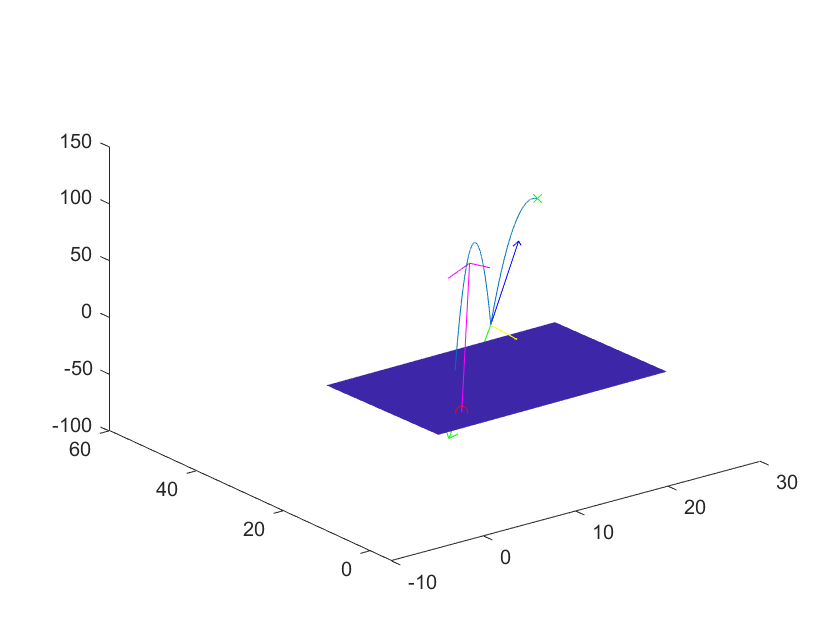


% begin plotting the plane
parallel = null(normal.');
p1 = parallel(:, 1);
p2 = parallel(:, 2);

Xbounds = [-5, 20];
Ybounds = [-5, 20];

[a, b] = meshgrid(Xbounds, Ybounds);
X = p1(1) * a + p2(1) * b + origin(1);
Y = p1(2) * a + p2(2) * b + origin(2);
Z = p1(3) * a + p2(3) * b + origin(3);

s = surf(X, Y, Z);
s.FaceColor = 'g';
shading flat